Control buck con integrador.


$$x_{k+1}=Ax_k+Bu_k$$


acción integral


$$u_k=Kx_k+\frac{Ki}{Ti}\sum_{i=1}^ky_{ref}-Cx_i$$



$$I_{k+1}=-Cx_k+I_k+y_{ref}$$



$$\hat x_{k+1}=\left(\begin{array}{cc} A & 0\\ -C & 1\end{array}\right)\hat x_k +\left(\begin{array}{c} B \\ 0 \end{array}\right)u_k+ \left(\begin{array}{c} 0 \\ 1 \end{array}\right)y_{ref}$$


clear
%%Buck Converter, Voltage drop, from 50 to 25V
%
L_1=100e-03; %Coil
C=1000e-06; %Capacitor
R=10; %Resistance
T=0.01; %Discretization period
V=200; %V_input
time=0.2;%Duration of the control action simmulation
A=[0 -1/L_1; 1/C -1/R/C]; %State matrix "Buck Converter"
B=[V/L_1; 0]; %Input matrix
V_o=0;%35;
I_o=0;%2;
Int_0=0;%90;
V_f=25;
lambda=0.9;
%Cd=[1 0];

Discretizamos el sistema

[PA,PB,alpha2]=discrete_binary_f(A,B,T)

PA =     0.6597   -0.0534
    5.3351    0.1262


PB =   2 MDCHP array with properties:

    grado: [1 1]
    n_var: [2 2]
     coef: {[2×1 double]  [2×1 double]  [2×1 double]  [2×1 double]}


alpha2 = 2×1 cell array
    {@(delta)(f_1(delta)-f_min)/(f_max-f_min)}
    {                           @(x)alpha1(x)}


Average model

A_avg=[0 -1/L_1; 1/C -1/R/C];
B_avg=[V/L_1; 0];
AVG=ss(A_avg,B_avg,[0 1],0);
Hd=c2d(AVG,T);
[Ad,Bd,Cd,Dd] = ssdata(Hd);

Augmented average model

Aa_avg=[Ad [0;0];-Cd 1];
Ba_avg=[Bd;0];

Controlador para AVG

r=rank(Aa_avg);
n=length(Aa_avg);


%%LMI optimization:
X5=sdpvar(n);
LMI5=[X5>=1e-8];
M5=sdpvar(1,n);
PQR5=[lambda^2*X5 X5*Aa_avg'+M5'*Ba_avg';Aa_avg*X5+Ba_avg*M5 X5];
LMI5=[LMI5 PQR5>=1e-8];
%LMI5=[ LMI5 [1 x0';x0 X5]>=1e-8];
%LMI5=[LMI5, [X5 M5';M5 1e6]>=1e-8]; 
optimize(LMI5);

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 9, order n = 10, dim = 46, blocks = 3
nnz(A) = 42 + 0, nnz(ADA) = 81, nnz(L) = 45
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.43E+00 0.000
  1 :   0.00E+00 1.36E+00 0.000 0.1827 0.9000 0.9000   1.00  1  1  1.4E+00
  2 :   0.00E+00 2.73E-01 0.000 0.2011 0.9000 0.9000   1.00  1  1  2.8E-01
  3 :   0.00E+00 7.60E-03 0.000 0.0278 0.9900 0.9900   1.00  1  1  7.8E-03
  4 :   0.00E+00 2.39E-07 0.000 0.0000 1.0000 1.0000   1.00  1  1  2.4E-07
  5 :   0.00E+00 2.54E-14 0.000 0.0000 1.0000 1.0000   1.00  1  1  1.0E-13

iter seconds digits       c*x               b*y
  5      0.1  11.1 -7.8773338553e-22  0.0000000000e+00
|Ax-b| =   2.5e-14, [Ay-c]_+ =   0.0E+00, |x|=  1.0e-13, |y|=  2.0e+00

Detailed timing (sec)
   Pre          IPM          Post
1.800E-02    3.200E-02    4.003E-03    
Max-norms: ||b||=0, ||c|| = 2.000000e-08,
Chole

K5=double(M5)*inv(double(X5));

alpha_3=sdpvar(1);
LMItest=[alpha_3>=1e-8];
P=inv(double(X5));
LMItest=[LMItest (Aa_avg+Ba_avg*K5)'*P*(Aa_avg+Ba_avg*K5)-alpha_3*P<=-1e-8];
optimize(LMItest,alpha_3)

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 1, order n = 5, dim = 11, blocks = 2
nnz(A) = 7 + 0, nnz(ADA) = 1, nnz(L) = 1
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.63E+00 0.000
  1 :  -9.73E-01 1.83E+00 0.000 0.2764 0.9000 0.9000   1.71  1  1  2.2E+00
  2 :  -6.18E-01 6.16E-01 0.000 0.3360 0.9000 0.9000   2.50  1  1  4.3E-01
  3 :  -6.43E-01 3.17E-02 0.000 0.0515 0.9900 0.9900   1.19  1  1  2.0E-02
  4 :  -6.46E-01 8.58E-05 0.000 0.0027 0.9990 0.9990   1.01  1  1  5.5E-05
  5 :  -6.46E-01 4.99E-06 0.000 0.0582 0.9900 0.9900   1.00  1  1  3.2E-06
  6 :  -6.46E-01 1.07E-06 0.000 0.2138 0.9000 0.9000   1.00  1  1  6.8E-07
  7 :  -6.46E-01 2.42E-07 0.000 0.2274 0.9000 0.9000   1.00  1  1  1.5E-07
  8 :  -6.46E-01 1.44E-08 0.000 0.0592 0.9900 0.9900   1.00  1  1  9.1E-09
  9 :  -6.46E-01 1.12E-09 0.375 0.0782 0.9900 0.9900   1.00  1  1  7.1E-10

iter seconds digits   

ans = struct with fields:
    yalmipversion: '20190425'
       yalmiptime: 0.1400
       solvertime: 0.0720
             info: 'Successfully solved (SeDuMi-1.3)'
          problem: 0


sqrt(double(alpha_3))

ans = 0.8036

sys=ss(Aa_avg+Ba_avg*K5,[0;0;1],[0 1 0],0,T)


sys =
 
  A = 
            x1       x2       x3
   x1  -0.6701   -0.203   0.1262
   x2   0.1562  -0.4566   0.4914
   x3        0       -1        1
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1   0   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



step(sys)

Controlador lineal para sistema borroso


PAa=[PA [0;0];-Cd 1];
PBa=[PB;0];
n=length(PAa);

X1=sdpvar(n);
LMI1=[X1>=1e-8];
% for i=1:PB.num_coef
%     M1{i}=sdpvar(1,n);
% end
% PM1=MDCHP(ones(1,2),2*ones(1,2),M1);
PM1=sdpvar(1,n);
PQR1=[lambda^2*X1 X1*PAa'+PM1'*PBa';PAa*X1+PBa*PM1 X1];
PQR1.Polya([4 4 4 4]);
coef1=PQR1.coef;
for i=1:length(coef1)
    LMI1=[LMI1 coef1{i}>=1e-8];
end
optimize(LMI1)

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 9, order n = 154, dim = 910, blocks = 27
nnz(A) = 906 + 0, nnz(ADA) = 81, nnz(L) = 45
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.92E+01 0.000
  1 :   0.00E+00 2.09E+01 0.000 0.3535 0.9000 0.9000   1.00  1  1  3.3E+01
  2 :   0.00E+00 6.18E+00 0.000 0.2951 0.9000 0.9000   1.00  1  1  9.9E+00
  3 :   0.00E+00 1.98E+00 0.000 0.3202 0.9000 0.9000   1.00  1  1  3.2E+00
  4 :   0.00E+00 6.22E-01 0.000 0.3146 0.9000 0.9000   1.00  1  1  9.9E-01
  5 :   0.00E+00 5.75E-02 0.000 0.0923 0.9900 0.9900   1.00  1  1  9.2E-02
  6 :   0.00E+00 3.67E-05 0.000 0.0006 0.9999 0.9999   1.00  1  1  5.9E-05
  7 :   0.00E+00 3.73E-12 0.000 0.0000 1.0000 1.0000   1.00  1  1  5.9E-12

iter seconds digits       c*x               b*y
  7      0.1   7.9 -1.2194193460e-18  0.0000000000e+00
|Ax-b| =   5.0e-12, [Ay-c]_+ =   0.0E+00, |x|=  4.5e-11, |y|=

ans = struct with fields:
    yalmipversion: '20190425'
       yalmiptime: 0.1315
       solvertime: 0.0835
             info: 'Successfully solved (SeDuMi-1.3)'
          problem: 0


K1=double(PM1)*inv(double(X1));
alpha_2=sdpvar(1);
LMItest=[alpha_2>=1e-8];
P=inv(double(X1));
PQR2=(PAa+PBa*K1)'*P*(PAa+PBa*K1)-alpha_2*P;
PQR2.Polya([4 4 4 4]);
coef2=PQR2.coef;
for i=1:length(coef2)
    LMItest=[LMItest coef2{i}<=-1e-8*eye(3)];
end
optimize(LMItest,alpha_2)

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 1, order n = 77, dim = 227, blocks = 26
nnz(A) = 151 + 0, nnz(ADA) = 1, nnz(L) = 1
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            3.10E+02 0.000
  1 :  -4.98E+00 6.95E+01 0.000 0.2244 0.9000 0.9000  -1.22  1  1  8.7E+02
  2 :  -8.63E+00 1.99E+01 0.000 0.2868 0.9000 0.9000   0.65  1  1  2.3E+02
  3 :  -4.08E+00 1.00E+01 0.000 0.5018 0.9000 0.9000   3.08  1  1  4.5E+01
  4 :  -9.14E-01 3.28E+00 0.000 0.3277 0.9000 0.9000   7.39  1  1  2.4E+00
  5 :  -7.99E-01 1.94E+00 0.000 0.5914 0.9000 0.9000   1.79  1  1  1.2E+00
  6 :  -8.21E-01 8.77E-01 0.000 0.4526 0.9000 0.9000   1.20  1  1  5.4E-01
  7 :  -7.92E-01 3.25E-02 0.000 0.0371 0.9900 0.9900   1.15  1  1  1.9E-02
  8 :  -7.92E-01 9.16E-05 0.000 0.0028 0.9990 0.9990   1.00  1  1  5.3E-05
  9 :  -7.92E-01 9.01E-06 0.338 0.0984 0.9900 0.9900   1.00  1  1  5.2E-06
 10 :  -7.92E-01 3

ans = struct with fields:
    yalmipversion: '20190425'
       yalmiptime: 0.1233
       solvertime: 0.1287
             info: 'Successfully solved (SeDuMi-1.3)'
          problem: 0


sqrt(double(alpha_2))

ans = 0.8901

Ahora las simulaciones control lineal sistema borroso

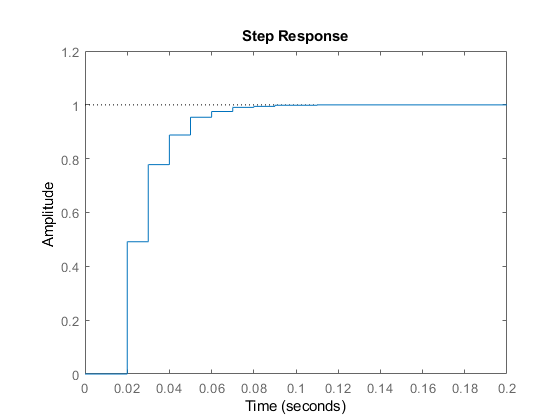

muT3=[];
alpha_sat1=[];
alpha_sat2=[];
r=2;
for i=1:r
    alpha_sat1=[alpha_sat1 1 0];
    alpha_sat2=[alpha_sat2 0 1];
end
Td=T/1000;
N=1000*(time/T);
t3c=[0 (1:N)*Td];
x3c=zeros(n,N);
x3c(:,1)=[I_o;V_o;V_f];
delta=0.125;
x=zeros(2,N);
y3=zeros(1,time/T);
y3(1)=V_o;
k=0;
for i=1:N
    if (mod(i,1000)==0)||(i==1)
        delta=K1*x3c(:,i);
%         Ki=K1*x3c(:,i);
%         aux=0;
%         delta=sum(Ki.array())/Ki.num_coef();
%         delta=delta*(delta<1)*(delta>0)+(delta>1);
%         delta_ant=-1;
%         while (aux<30)&&(abs(delta-delta_ant)>1e-6)
%             aux=aux+1;
%             delta_ant=delta;
%             alpha=[];
%             for j=1:r
%                 alpha=[alpha (1-alpha2{j}(delta)) alpha2{j}(delta)];
%             end
%             delta=Ki.eval(alpha);
%             delta=(delta+delta_ant)/2;
%         end
%         
%         aux;
        k=k+1;
        y3(k)=x3c(2,i);
        muT3=[muT3 delta];
    end
    
%     delta;
%     alpha;
    if (delta>1)||(isnan(delta))
        delta=1;
        %alpha=alpha_sat2;
    elseif delta<0
        delta=0;
        %alpha=alpha_sat1;
    end
    if (mod(i,1000)/1000<delta)
       x3c(1:2,i+1)=x3c(1:2,i)+Td*(A*x3c(1:2,i)+B);
    else
       x3c(1:2,i+1)=x3c(1:2,i)+ Td*A*x3c(1:2,i);
    end
    if (mod(i,1000)==0)||(i==1)%&&(delta~=0)&&(delta~=1)
        x3c(3,i+1)=x3c(3,i)-[0 1]*x3c(1:2,i)+V_f;
    else
        x3c(3,i+1)=x3c(3,i);
    end

    if (x3c(1,i+1)<0)
        x3c(1,i+1)=0;
    end
    %muT3=[muT3 delta];
    %x3(:,i+1)=PA*x3(:,i)+PB.eval(alpha)*delta;    
end
hold off

plot(t3c,x3c(2,:)','g')
hold on
plot(0:T:0.2,y3,'og')

Controlador borrosos sistema borroso

PAa=[PA [0;0];-Cd 1];
PBa=[PB;0];
n=length(PAa);

X1=sdpvar(n);
LMI1=[X1>=1e-8];
for i=1:PB.num_coef
    M1{i}=sdpvar(1,n);
end
PM1=MDCHP(ones(1,2),2*ones(1,2),M1);
%PM1=sdpvar(1,n);
PQR1=[lambda^2*X1 X1*PAa'+PM1'*PBa';PAa*X1+PBa*PM1 X1];
PQR1.Polya([4 4 4 4]);
coef1=PQR1.coef;
for i=1:length(coef1)
    LMI1=[LMI1 coef1{i}>=1e-8];
end
optimize(LMI1)

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 18, order n = 154, dim = 910, blocks = 27
nnz(A) = 1140 + 0, nnz(ADA) = 324, nnz(L) = 171
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.92E+01 0.000
  1 :   0.00E+00 1.24E+01 0.000 0.2101 0.9000 0.9000   1.00  1  1  2.0E+01
  2 :   0.00E+00 2.79E+00 0.000 0.2239 0.9000 0.9000   1.00  1  1  4.4E+00
  3 :   0.00E+00 1.50E-01 0.000 0.0538 0.9900 0.9900   1.00  1  1  2.4E-01
  4 :   0.00E+00 4.82E-05 0.000 0.0003 0.9999 0.9999   1.00  1  1  7.7E-05
  5 :   0.00E+00 4.87E-12 0.000 0.0000 1.0000 1.0000   1.00  1  1  7.8E-12

iter seconds digits       c*x               b*y
  5      0.2   8.5 -3.2204558870e-19  0.0000000000e+00
|Ax-b| =   6.6e-12, [Ay-c]_+ =   0.0E+00, |x|=  8.2e-12, |y|=  2.1e+00

Detailed timing (sec)
   Pre          IPM          Post
6.005E-03    7.000E-02    4.003E-03    
Max-norms: ||b||=0, ||c|| = 2.000000e-0

ans = struct with fields:
    yalmipversion: '20190425'
       yalmiptime: 0.1111
       solvertime: 0.0839
             info: 'Successfully solved (SeDuMi-1.3)'
          problem: 0


K2=double(PM1)*inv(double(X1));
alpha_2=sdpvar(1);
LMItest=[alpha_2>=1e-8];
P=inv(double(X1));
PQR2=(PAa+PBa*K2)'*P*(PAa+PBa*K2)-alpha_2*P;
PQR2.Polya([4 4 4 4]);
coef2=PQR2.coef;
for i=1:length(coef2)
    LMItest=[LMItest coef2{i}<=-1e-8*eye(3)];
end
optimize(LMItest,alpha_2)

SeDuMi 1.3 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 1, order n = 77, dim = 227, blocks = 26
nnz(A) = 151 + 0, nnz(ADA) = 1, nnz(L) = 1
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.29E+02 0.000
  1 :  -1.08E+00 2.83E+01 0.000 0.2199 0.9000 0.9000   1.79  1  1  3.2E+01
  2 :  -1.08E+00 2.06E+00 0.000 0.0727 0.9900 0.9900   1.70  1  1  1.5E+00
  3 :  -1.03E+00 1.73E-01 0.000 0.0841 0.9900 0.9900   1.35  1  1  1.2E-01
  4 :  -1.03E+00 1.29E-04 0.000 0.0007 0.9999 0.9999   1.01  1  1  8.7E-05
  5 :  -1.03E+00 5.66E-06 0.054 0.0440 0.9900 0.9900   1.00  1  1  3.8E-06
  6 :  -1.03E+00 1.48E-07 0.000 0.0262 0.9900 0.9900   1.00  1  1  1.0E-07
  7 :  -1.03E+00 6.77E-09 0.000 0.0457 0.9900 0.9900   1.00  1  1  4.6E-09
  8 :  -1.03E+00 5.02E-10 0.000 0.0742 0.9900 0.9900   1.00  1  1  3.4E-10

iter seconds digits       c*x               b*y
  8      0.1   9.9 -1.0265060261e+00 -1.0265

ans = struct with fields:
    yalmipversion: '20190425'
       yalmiptime: 0.1194
       solvertime: 0.0816
             info: 'Successfully solved (SeDuMi-1.3)'
          problem: 0


sqrt(double(alpha_2))

ans = 1.0132

Ahora las simulaciones control borroso sistema borroso

muT4=[];
alpha_sat1=[];
alpha_sat2=[];
r=2;
for i=1:r
    alpha_sat1=[alpha_sat1 1 0];
    alpha_sat2=[alpha_sat2 0 1];
end
Td=T/1000;
N=1000*(time/T);
t4c=[0 (1:N)*Td];
x4c=zeros(n,N);
x4c(:,1)=[I_o;V_o;V_f];
delta=0.125;
x=zeros(2,N);
y4=zeros(1,time/T);
y4(1)=V_o;
k=0;
for i=1:N
    if (mod(i,1000)==0)||(i==1)
        
        Ki=K2*x4c(:,i);
        aux=0;
        delta=sum(Ki.array())/Ki.num_coef();
        delta=delta*(delta<1)*(delta>0)+(delta>1);
        delta_ant=-1;
        while (aux<30)&&(abs(delta-delta_ant)>1e-6)
            aux=aux+1;
            delta_ant=delta;
            alpha=[];
            for j=1:r
                alpha=[alpha (1-alpha2{j}(delta)) alpha2{j}(delta)];
            end
            delta=Ki.eval(alpha);
            delta=(delta+delta_ant)/2;
        end
        
        aux;
        k=k+1;
        y4(k)=x4c(2,i);
        muT4=[muT4 delta];
    end
    
%     delta;
%     alpha;
    if (delta>1)||(isnan(delta))
        delta=1;
        %alpha=alpha_sat2;
    elseif delta<0
        delta=0;
        %alpha=alpha_sat1;
    end
    if (mod(i,1000)/1000<delta)
       x4c(1:2,i+1)=x4c(1:2,i)+Td*(A*x4c(1:2,i)+B);
    else
       x4c(1:2,i+1)=x4c(1:2,i)+ Td*A*x4c(1:2,i);
    end
    if (mod(i,1000)==0)||(i==1)%&&(delta~=0)&&(delta~=1)
        x4c(3,i+1)=x4c(3,i)-[0 1]*x4c(1:2,i)+V_f;
    else
        x4c(3,i+1)=x4c(3,i);
    end

    if (x4c(1,i+1)<0)
        x4c(1,i+1)=0;
    end
    %muT3=[muT3 delta];
    %x3(:,i+1)=PA*x3(:,i)+PB.eval(alpha)*delta;    
end
plot(t4c,x4c(2,:)','b')
hold on
plot(0:T:0.2,y4,'ob')

Ahora las simulaciones control avg

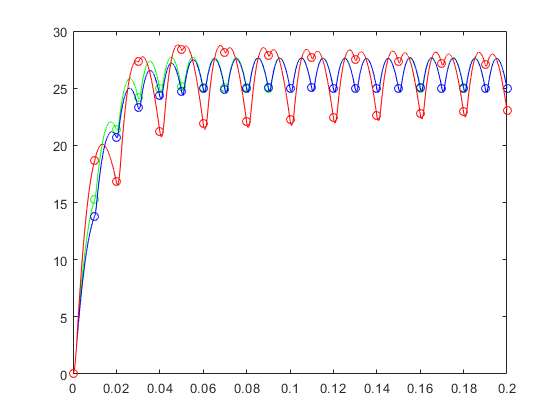

Td=T/1000;
N=1000*(time/T);
t7c=[0 (1:N)*Td];
x7c=zeros(n,N);
x7c(:,1)=[I_o;V_o;V_f];
y7=zeros(1,time/T);
x=zeros(2,N);
k=0;
x7=[];
muT7c=[];
for i=1:N
    if (mod(i,1000)==0)||(i==1)
        delta=K5*(x7c(:,i));
        x7=[x7 x7c(:,i)];
        if (delta>=1)||(isnan(delta))
            delta=1;
        elseif delta<0
            delta=0;
        end
        k=k+1;
        muT7c=[muT7c delta]; 
        y7(k)=x7c(2,i);
    end
    
%     delta;
%     alpha;
    
    if (mod(i,1000)/1000<(delta))
       x7c(1:2,i+1)=x7c(1:2,i)+Td*(A*x7c(1:2,i)+B);
    else
       x7c(1:2,i+1)=x7c(1:2,i)+ Td*A*x7c(1:2,i);
    end
    if (mod(i,1000)==0)||(i==1)%&&(delta~=0)&&(delta~=1))
        x7c(3,i+1)=x7c(3,i)-[0 1]*x7c(1:2,i)+V_f;
    else
        x7c(3,i+1)=x7c(3,i);
    end
    if (x7c(1,i+1)<0)
        x7c(1,i+1)=0;
    end
   
end
hold on
plot(t7c,x7c(2,:)','r')
plot(0:T:0.2,y7,'or')

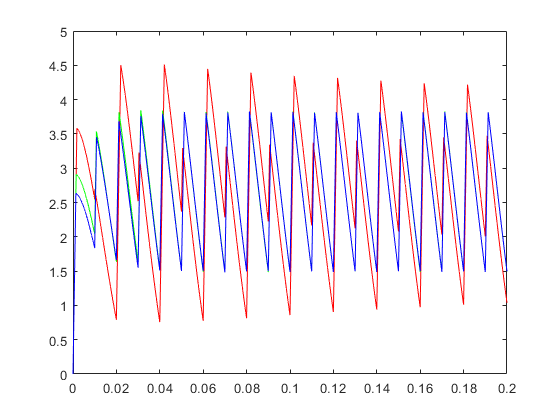

figure
plot(t7c,x7c(1,:)','r')
hold on
plot(t3c,x3c(1,:)','g')
plot(t4c,x4c(1,:)','b')

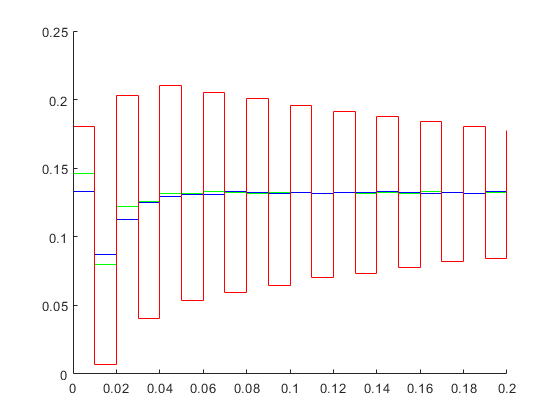



figure

hold on

stairs(0:T:0.2,muT3,'g')
stairs(0:T:0.2,muT4,'b')
stairs(0:T:0.2,muT7c,'r')